# **Circuitos Electricos II**

**Roberto Sanchez Figueroa**

**brrsanchezfi@unal.edu.co**

***Monitoria Circuitos II***

***GIT-HUB:  ***[***https://github.com/brrsanchezfi/Circuitos_2022_1***](https://github.com/brrsanchezfi/Circuitos_2022_1)

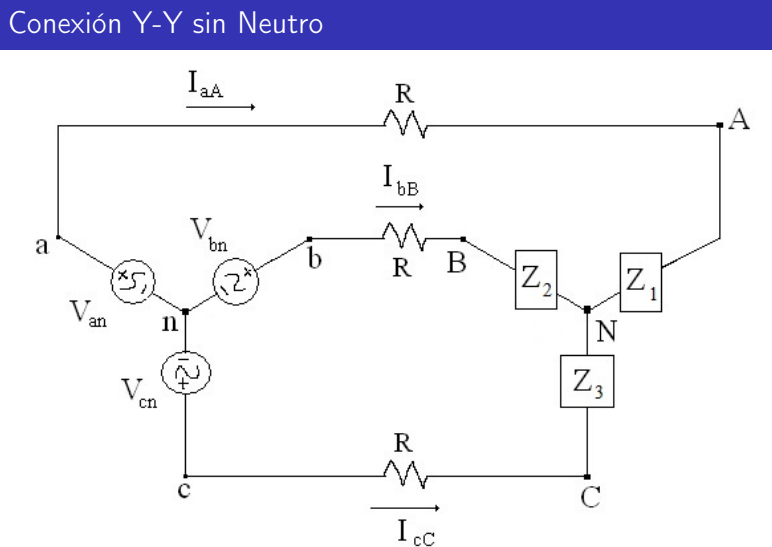

## Matlab simbolico

## 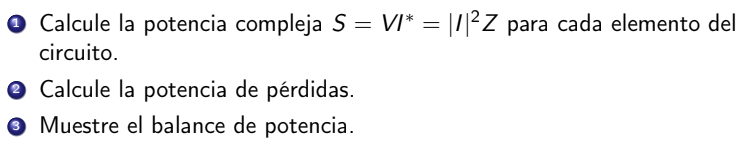

%Valores numericos

R = 0.5;
Z1 = 5 + 5i;
Z2 = 5 + 5i;
Z3 = 5 + 5i;
Van = pol_com(100/sqrt(2),0)

Van = 70.7107

Vbn = pol_com(100/sqrt(2),-120)  %Valores RMS  (mayus es RMS)

Vbn = -35.3553 - 61.2372i

Vcn = pol_com(100/sqrt(2),120)

Vcn = -35.3553 + 61.2372i


syms I_1 I_2 I_3 Z_1 Z_2 Z_3 R_L V_an V_bn V_cn

sys = [V_an - V_bn == I_1*(Z_1 + R_L + Z_2 + R_L) - I_2*(R_L + Z_2);
       V_bn - V_cn == I_2*(R_L + Z_2 + Z_3 + R_L) - I_1*(Z_2 + R_L)]

$$sys = \left(\begin{array}{c} V_{\mathrm{an}}-V_{\mathrm{bn}}=I_{1}\,\left(2\,R_{L}+Z_{1}+Z_{2}\right)-I_{2}\,\left(R_{L}+Z_{2}\right)\\ V_{\mathrm{bn}}-V_{\mathrm{cn}}=I_{2}\,\left(2\,R_{L}+Z_{2}+Z_{3}\right)-I_{1}\,\left(R_{L}+Z_{2}\right) \end{array}\right)$$

sol = solve(sys,[I_1 I_2]);


%Corrientes de Malla
I_1 = simplify(sol.I_1);
I_2 = simplify(sol.I_2);
I_1 = subs(I_1,[Z_1 Z_2 Z_3 R_L V_an V_bn V_cn],[Z1 Z2 Z3 R Van Vbn Vcn]);
I_2 = subs(I_2,[Z_1 Z_2 Z_3 R_L V_an V_bn V_cn],[Z1 Z2 Z3 R Van Vbn Vcn]);

%Corriente de Linea
I_aA = double(I_1)

I_aA = 7.0391 - 6.3992i

I_bB = double(I_2 - I_1)

I_bB = -9.0614 - 2.8964i

I_cC = double(-I_2)

I_cC = 2.0223 + 9.2956i

%Potencia compleja S    
S_l1 =  V_an*conj(I_aA); %potencia linea 1 l1
S_l2 =  V_bn*conj(I_bB);
S_l3 =  V_cn*conj(I_cC);

S_total = (S_l1 + S_l2 + S_l3);
S_total = double(subs(S_total,[V_an V_bn V_cn],[Van Vbn Vcn]))

S_total = 1.4932e+03 + 1.3575e+03i

%Potencia de perdidas
S_lp1 = double(abs(I_aA)^2 * R);  %Potencia de perdidas linea 1 lp1
S_lp2 = double(abs(I_bB)^2 * R);
S_lp3 = double(abs(I_cC)^2 * R);
S_tp = S_lp1 + S_lp2 + S_lp3 % potencia total de perdidas

S_tp = 135.7466

%Potencia de carga
S_tc = (abs(I_aA)^2*(Z1) +abs(I_bB)^2*(Z2) + abs(I_cC)^2*(Z3)) %potencia total de carga

S_tc = 1.3575e+03 + 1.3575e+03i

%Balance de potencia
Balance = round(S_total - (S_tc + S_tp)) %potencia de la fuente - (potencia carga + potencia de perdidas)

Balance = 0

## Simulacion

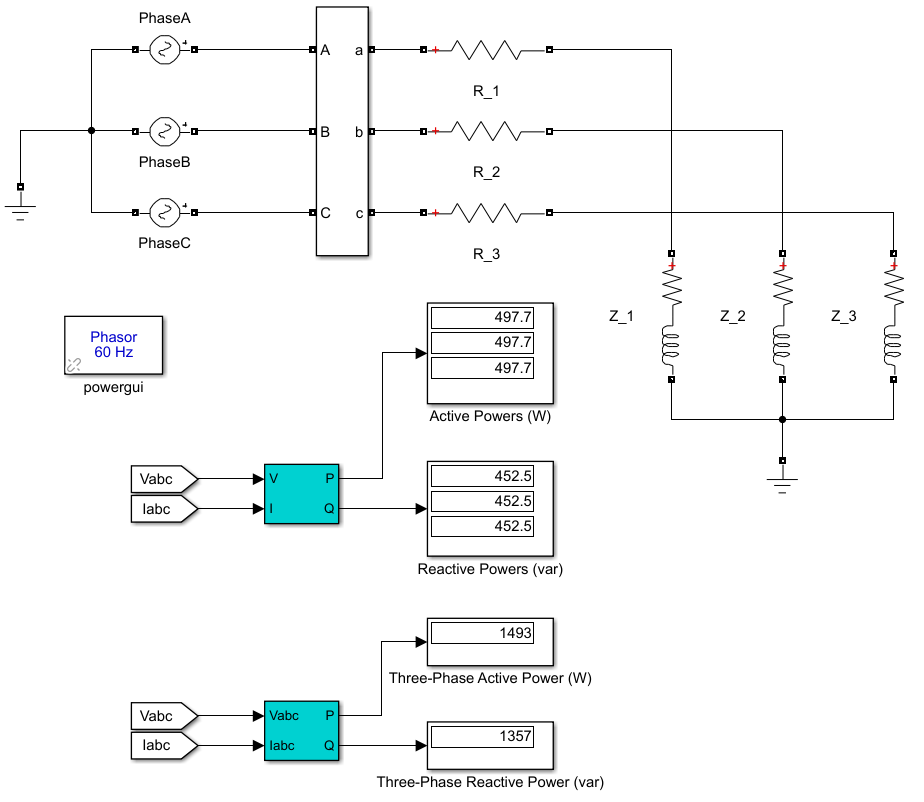

function Complejo = pol_com(M,A)  % magnitud, angulo

Complejo = M * exp (deg2rad (A) * 1i); 

end